# Problem set #1

1. What areas of finance are of most interest to you?

    Quantatitive Investment. All the topics are interesting as long as they have  some connection with investment.  I prefer to learn techiques used in buy-side company if I have choices. Machine learning, blockchain, and other new stuffs are more interesting from my perspective, instead of some old knowledge like Markowitz or CAPM.

    All in all. I am interested in all kinds of hands-on experiences instead of those theoretical stuffs. Of course theories are important, but I prefer to learn them directly when I "use" them.

2.  What is the primary reason for your interest in this course?

    Programming is always attractive to me. I think this is the way to put theory into practice. I take this course mainly because it's the place where I have a lot of oppotunities to code and get exposed to some practical problems faced by a quant.

3. List all programming languages you have used and your level of familiarity with each.

    Python -- fluent;

    R -- somewhat fluent;

    Matlab -- somewhat fluent;

    C++ -- okay;

    SAS -- advanced programmer candidate (but long time ago)

4. Option traders often say that when buying options we get gamma at the expense of theta, What do you think they mean?

    One cannot solve these two problems simultaneously by hedging gamma and at the same time, hedging theta. In other words, it's inevitable that one need to choose one to hedge and get exposed to the other.

    By the way, I expect to face with something different with MF803 instead of having the oppotunities to use the same code or answer the same question in MF803.

5. Consider the CEV Model:

#### 
$$dS_t =rS_t \mathrm{dt}+\sigma S_t^{\beta } dW_t$$


    Assume:

s0 = 100; r = 0.0; beta = 1.0; sigma = 0.25;

(a) Describe what each model parameter does.

    $S_0$ is starting point of the stochastic process;

    $rS_t \mathrm{dt}$ is the drift term, determining the direction of the process; r generally controls the orientation and magnitude of the drift.

    $\sigma S_t^{\beta } dW_t$ is the noise term, schochastic part of the PDE. $\sigma S_t^{\beta }$ controls the volatilty of the normal distributed randomness. In this case, beta = 1.0 relegates the model to BS model.

(b) Price an at-the-money one year European call option via monte carlo simulation.

T = 1; n = 10000;% parameter for monte carlo simulation
s_path = CEV_monte_carlo(s0,r,sigma,beta,T,n); % asset paths
st = s_path(end,:); % end values
k = 100; % strike price
payoff = european_payoff(k, 1, 1, st); % payoff of european call option
prc_sim = 1/n * sum(discount(r, T, payoff)) % price under LLN

prc_sim = 9.7593

(c) Calculate the price of the same European call option via the Black-Scholes formula. Is this price the same as you obtained via simulation? Should it be? Why or why not? 

    According Black–Scholes formula:


$$c=N\left(d_1 \right)S_0 -N\left(d_2 \right)e^{-r*T} K$$



$$d_1 =\frac{\mathrm{ln}\frac{S_0 }{K}+\left(r+\frac{\sigma^2 }{2}\right)T}{\sigma \sqrt{T}}$$



$$d_2 =d_1 -\sigma \sqrt{T}$$


d1 = (log(s0 / k) + (r + 0.5 * sigma ^ 2) * T) / (sigma * sqrt(T));
d2 = (log(s0 / k) + (r - 0.5 * sigma ^ 2) * T) / (sigma * sqrt(T));
prc_bs = normcdf(d1) * s0 - normcdf(d2) * discount(r, T, k); % price under BS

    These two prices should be similar but not exactly the same. And Indeed, the price from simulation is 

prc_sim

prc_sim = 9.7593

    while the price from BS formula is 

prc_bs

prc_bs = 9.9476

    According to law of large num(LLN), the price from simulation will converge to the one from BS model. But might not be exactly the same.

(d) In the Black-Scholes model, we know that the delta of a European call option is:


$$\Delta =\Phi \left(d_1 \right)$$



$$d_1 =\frac{\ln \frac{S_0 }{K}+\left(r+\frac{\sigma^2 }{2}\right)T}{\sigma \sqrt{T}}$$


delta = normcdf(d1)

delta = 0.5497

(e) Using the delta obtained above, calculate how many shares of stock you need to construct a delta neutral portfolio that is long one unit of the call option and short ∆ shares of the stock?

    So we should short ∆ = 0.5487 shares of the stock.

(f) Use simulation to estimate the payoff of the delta neutral portfolio obtained above. How does the payoff compare to the Black-Scholes model price of the option you obtained earlier? What conditions cause this portfolio to make money? Lose money?

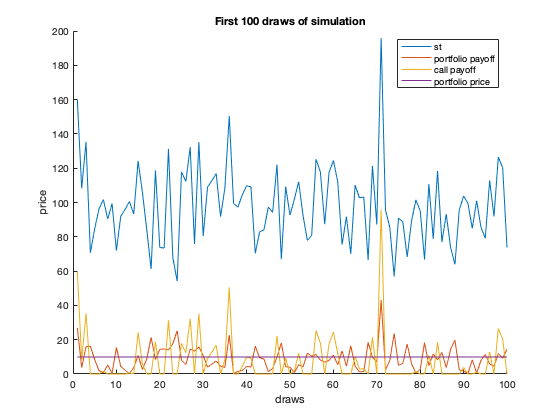

stk_payoff = - delta * (st - s0); % payoff of stocks
port_payoff = stk_payoff + payoff; % payoff of portfolio
port_prc = 1/n * sum(discount(r, T, port_payoff)); % price of portfolio
plot1([st(1:100)',port_payoff(1:100)',payoff(1:100)',ones(100,1)*port_prc])

    the payoff pattern changed from aggressively making profit from extreme stock surge to more mild distribution. this portfolio would make money if stock price hugly deviate from its intial value, and would lose money if there is limited change of the stock price.

(g) Modify the model dynamics so that β = 0.5 and all other parameters are the same as in the original question. Using the same hedging portfolio perform another simulation to estimate the payoffs of the delta-neutral portfolio under these dynamics. Are the payoffs higher or lower? Why?

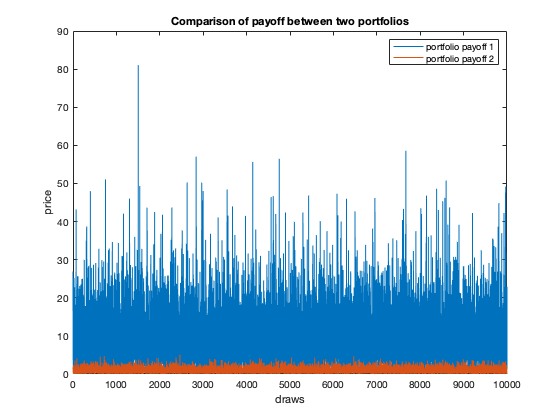

beta2 = 0.5;
s_path2 = CEV_monte_carlo(s0,r,sigma,beta2,T,n); % asset paths
st2 = s_path2(end,:); % end values
stk_payoff2 = - delta * (st2 - s0); % payoff of stocks
payoff2 = european_payoff(k, 1, 1, st2); % payoff of european call option
port_payoff2 = stk_payoff2 + payoff2; % payoff of portfolio
plot2([port_payoff',port_payoff2'])

    the payoffs of portfolio 2 is much lower of those of portfolio 1.

(h) Modify the model dynamics so that σ = 0.4 and all other parameters are the same as in the original question. Using the same hedging portfolio perform another simulation to estimate the payoffs of the delta-neutral portfolio under these dynamics. Explain the relationship between a delta-neutral portfolio and the σ parameter.

sigma2 = 0.4;
d1_2 = (log(s0 / k) + (r + 0.5 * sigma2 ^ 2) * T) / (sigma2 * sqrt(T));
delta2 = normcdf(d1_2)

delta2 = 0.5793

s_path3 = CEV_monte_carlo(s0,r,sigma2,beta,T,n); % asset paths
st3 = s_path3(end,:); % end values
stk_payoff3 = - delta2 * (st3 - s0); % payoff of stocks
payoff3 = european_payoff(k, 1, 1, st3); % payoff of european call option
port_payoff3 = stk_payoff3 + payoff3; % payoff of portfolio
mean(port_payoff)

ans = 9.9267

mean(port_payoff3)

ans = 15.7702

    When sigma gets larger, the payoff of delta-neutral portfolio is larger.